cd 'G:\My Drive\PhD_Research\BSF_Thesis\ModernAndSurfaceProcesses\Analyses\ModProcAnalyses\Figures\FigureS1etPPTpet'
cd data\input\
load('MasonKipp_1993-1994.mat')
load("MasonKipp_PPT.mat")
MasonKipp_Evap_1994 = MasonKipp_complete;
clear MasonKipp_complete
load('KENV_WeatherData.mat')

cd ..\output\

MasonKipp_monthly = retime(MasonKipp_Evap_1994, "monthly",'mean');
MasonKipp_monthly_Sum = retime(MasonKipp_Evap_1994, "monthly",'sum');
%remove data with incomplete monthly coverage
MasonKipp_monthly_Sum.Margin_PET_mmDay(1) = NaN;
MasonKipp_monthly_Sum.Margin_ET_mmDay(1) = NaN;
MasonKipp_monthly_Sum = outerjoin(MasonKipp_monthly_Sum, MasonKippBSF_PPT,'Type','left');

## Create Figure S1

tiledlayout (4,3)

nexttile
scatter(MasonKipp_monthly.Crust_ET_mmDay, MasonKipp_monthly.Margin_ET_mmDay,'DisplayName','monthly average')
hold on 
plot([0,1.5],[0,1.5],'DisplayName','1:1 fit')
legend("Location",'southeast')

xlabel('crust E (mm day^-^1)')
ylabel('margin E (mm day^-^1)')

nexttile
hold on 
scatter(MasonKipp_monthly.Crust_PET_mmDay, MasonKipp_monthly.Margin_PET_mmDay)
plot([0,8],[0,8])
xlabel('crust PE (mm day^-^1)')
ylabel('margin PE (mm day^-^1)')

nexttile
hold on 
scatter(MasonKippBSF_PPT.CrustmmPPT(12:33), MasonKippBSF_PPT.MarginmmPPT(12:33))
plot([0,35],[0,35])
xlabel('crust PPT (mm month^-^1)')
ylabel('margin PPT (mm month^-^1)')


nexttile([1,3])
hold on 
figure
[fitting, error] = fit(KENVWeatherData.Year, KENVWeatherData.TotalPPT, 'poly1')

fitting =      Linear model Poly1:
     fitting(x) = p1*x + p2
     Coefficients (with 95% confidence bounds):
       p1 =     -0.3706  (-0.6543, -0.08681)
       p2 =         843  (285.1, 1401)

error = struct with fields:
           sse: 2.3659e+05
       rsquare: 0.0589
           dfe: 107
    adjrsquare: 0.0501
          rmse: 47.0227


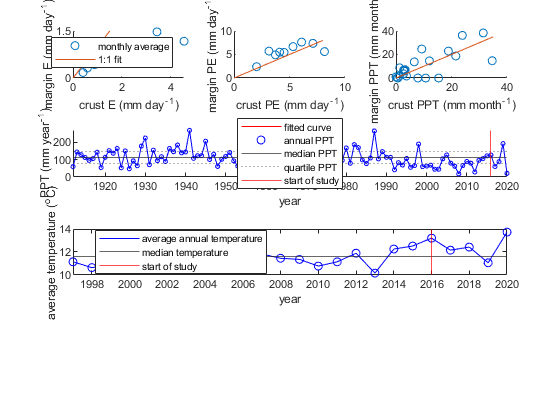

% plot(fitting)
plot(KENVWeatherData.Year, KENVWeatherData.TotalPPT, 'color', 'blue','HandleVisibility',"off")

scatter(KENVWeatherData.Year, KENVWeatherData.TotalPPT,10, 'blue','DisplayName','annual PPT')
ylim([0,270])
xlim([1912,2020])
yline(110.87, 'DisplayName','median PPT')
yline(79.2,':', 'DisplayName','quartile PPT')
yline(144.01,':', 'DisplayName','quartile', 'HandleVisibility',"off")
xline(2016,'red', 'displayname','start of study')
legend('location', 'best')
xlabel('year')
ylabel('PPT (mm year^-^1)')

nexttile([1,3])

plot(KENVWeatherData.Year, KENVWeatherData.AverageAirTemperature, 'color', 'blue', 'DisplayName', 'average annual temperature')
hold on
scatter(KENVWeatherData.Year, KENVWeatherData.AverageAirTemperature, 'blue','HandleVisibility','off')
xlim([1997,2020])

xlabel('year')
ylabel('average temperature (^oC)')
yline(median(KENVWeatherData.AverageAirTemperature, 'omitnan'), 'DisplayName','median temperature')
xline(2016,'red', 'displayname','start of study')
legend('location', 'best')

print('FigureS1', '-fillpage','-dpdf') %'-bestfit' -fillpage